# Data preparation: cleaning

The data in "biopsies_raw.csv" has not been cleaned:

clear all;
data = readtable('biopsies_raw.csv')

data = 570×32 table
       id         diagnosis      radius_mean    texture_mean    perimeter_mean    area_mean    smoothness_mean    compactness_mean    concavity_mean    concavePoints_mean    symmetry_mean    fractal_dimension_mean    radius_se    texture_se    perimeter_se    area_se    smoothness_se    compactness_se    concavity_se    concavePoints_se    symmetry_se    fractal_dimension_se    radius_worst    texture_worst    perimeter_worst    area_worst    smoothness_worst    compactness_worst    concavit

Clean the data and split it ready for training and testing a classifier.

Marks are available for:

- Appropriately addressing: duplicated examples; irrelevant features; missing values [5 marks]

- Identifying and removing the extreme outlier for the "smoothness_mean" feature [3 marks]

- Splitting the data up into an appropriately named training dataset and testing dataset [8 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

% add as many lines of code as you need below:
%Calls the unique() (this returns all the unique rows from the data set) function giving the data as the parameter, 'rows' is
%also given so that the function only returns unique rows from the data and
%'stable' is given so that the output is not sorted. This is done as when
%data is exported sometimes there can be duplicated data, this is not
%needed when training or testing a classifier.
myData = unique(data, 'rows', 'stable')

myData = 569×32 table
       id         diagnosis      radius_mean    texture_mean    perimeter_mean    area_mean    smoothness_mean    compactness_mean    concavity_mean    concavePoints_mean    symmetry_mean    fractal_dimension_mean    radius_se    texture_se    perimeter_se    area_se    smoothness_se    compactness_se    concavity_se    concavePoints_se    symmetry_se    fractal_dimension_se    radius_worst    texture_worst    perimeter_worst    area_worst    smoothness_worst    compactness_worst    concav


%Removes the 'id' column from the data as 'id' is an irrelevant feature
%within the given data set, also a summary is provided to check this column
%has been removed correctly.
myData(:,'id') = []

myData = 569×31 table
      diagnosis      radius_mean    texture_mean    perimeter_mean    area_mean    smoothness_mean    compactness_mean    concavity_mean    concavePoints_mean    symmetry_mean    fractal_dimension_mean    radius_se    texture_se    perimeter_se    area_se    smoothness_se    compactness_se    concavity_se    concavePoints_se    symmetry_se    fractal_dimension_se    radius_worst    texture_worst    perimeter_worst    area_worst    smoothness_worst    compactness_worst    concavity_worst    

summary(myData)

Variables:

    diagnosis: 569×1 cell array of character vectors

        Properties:
            Description:  diagnosis
    radius_mean: 569×1 double

        Properties:
            Description:  radius_mean
        Values:

            Min             6.981   
            Median          13.355  
            Max             28.11   
            NumMissing      1       

    texture_mean: 569×1 double

        Properties:
            Description:  texture_mean
        Values:

            Min         9.71  
            Median     18.84  
            Max        39.28  

    perimeter_mean: 569×1 double

        Properties:
            Description:  perimeter_mean
        Values:

            Min        43.79  
            Median     86.24  
            Max        188.5  

    area_mean: 569×1 double

        Properties:
            Description:  area_mean
        Values:

            Min        143.5


%Uses the 'isnan' function on the radius mean feature column to find the
%indices of missing values, the rows at this index are then removed from
%the dataset entirely, also a summary is provided to check they have been
%removed correctly
myData(isnan(myData{:, 'radius_mean'}),:) = []

myData = 568×31 table
      diagnosis      radius_mean    texture_mean    perimeter_mean    area_mean    smoothness_mean    compactness_mean    concavity_mean    concavePoints_mean    symmetry_mean    fractal_dimension_mean    radius_se    texture_se    perimeter_se    area_se    smoothness_se    compactness_se    concavity_se    concavePoints_se    symmetry_se    fractal_dimension_se    radius_worst    texture_worst    perimeter_worst    area_worst    smoothness_worst    compactness_worst    concavity_worst    

summary(myData)

Variables:

    diagnosis: 568×1 cell array of character vectors

        Properties:
            Description:  diagnosis
    radius_mean: 568×1 double

        Properties:
            Description:  radius_mean
        Values:

            Min         6.981 
            Median     13.355 
            Max         28.11 

    texture_mean: 568×1 double

        Properties:
            Description:  texture_mean
        Values:

            Min          9.71 
            Median     18.855 
            Max         39.28 

    perimeter_mean: 568×1 double

        Properties:
            Description:  perimeter_mean
        Values:

            Min        43.79  
            Median     86.21  
            Max        188.5  

    area_mean: 568×1 double

        Properties:
            Description:  area_mean
        Values:

            Min         143.5 
            Median     548.75 
            Max      

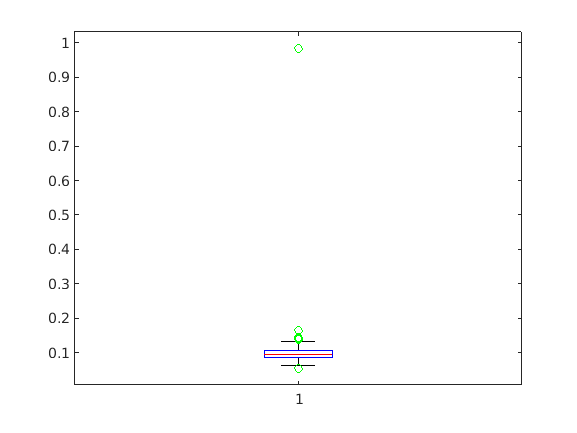


%create a boxplot of the 'smoothness_mean' feature column, using this
%boxplot you can find the greatest outlier, this outlier is then removed
%then another boxplot is created to check it was removed correctly
boxplot(myData{:,'smoothness_mean'}, 'symbol', 'go')

myData(159,:) = []

myData = 567×31 table
      diagnosis      radius_mean    texture_mean    perimeter_mean    area_mean    smoothness_mean    compactness_mean    concavity_mean    concavePoints_mean    symmetry_mean    fractal_dimension_mean    radius_se    texture_se    perimeter_se    area_se    smoothness_se    compactness_se    concavity_se    concavePoints_se    symmetry_se    fractal_dimension_se    radius_worst    texture_worst    perimeter_worst    area_worst    smoothness_worst    compactness_worst    concavity_worst    

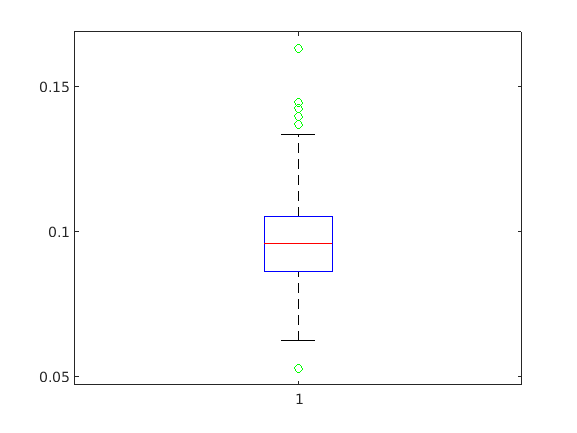

boxplot(myData{:,'smoothness_mean'}, 'symbol', 'go')


%the number of test data used is calculated (25% of the data) 
nTest = round(0.25 * size(data,1))

nTest =    143


% Re-seed matlabs random number generator
% with a value of 1, this means the set of random numbers generated will be the same each time, this is so results can be cross-compared and discussed
rng(1)
% Shuffles the rows of the table by indexing the 'data' table using a random permutation of integers from 1 to the size of the table and stores
% the shuffled table in 'data_shuffled', the data needs to be shuffled as
% datasets are often sorted before being exported, if we were to split up
% sorted data into training and testing sets then both new sets would
% contain unrepresentative data 
data_shuffled = myData(randperm(size(myData,1)), :);
% split up the data into test data (25%) and training data (75%)
data_test = data_shuffled(1:1:nTest, :);
size(data_test)

ans =    143    31


data_train = data_shuffled(nTest+1:1:end, :);
size(data_train)

ans =    424    31
